close all
clear 
clc

`评分标准：数值计算占10%，思路占90%。数值结果不影响问题的求解思路。`

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

第1题（15分）

绕固定轴ZYX序列以$\alpha_1=-\pi / 2$，$\alpha_2=-\pi / 4$及$\alpha_3=\pi / 4$的旋转三次，请写出最终得到的坐标变换矩阵为$\bf{R}$的表达式。如有一个单位向量$\bf{r} \in \mathbb{R}^3$，使得$\bf{r} = \bf{R} \bf{r} $，请描述如何求解$\bf{r} $。

解答：

（1）列写基本坐标变换举着（每个2分）

Rz = rotz(-pi/2)

Rz =      0     1     0
    -1     0     0
     0     0     1


Ry = roty(-pi/4)

Ry =     0.7071         0   -0.7071
         0    1.0000         0
    0.7071         0    0.7071


Rx = rotx(pi/4)

Rx =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


（2）固定轴旋转概念（3分）

R = Rx*Ry*Rz

R =          0    0.7071   -0.7071
   -0.7071   -0.5000   -0.5000
   -0.7071    0.5000    0.5000


（3）求特征值及特征向量，取特征值为1的特征向量（此处为第3个）（5分）

[V, D] = eig(R)

V =    0.0000 - 0.5774i   0.0000 + 0.5774i  -0.5774 + 0.0000i
   0.7071 + 0.0000i   0.7071 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 - 0.4082i  -0.0000 + 0.4082i   0.8165 + 0.0000i


D =   -0.5000 + 0.8660i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5000 - 0.8660i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


（4）列出$\bf{r} $，注意加正负号（1分）

r1 = V(:,3)

r1 =    -0.5774
   -0.0000
    0.8165


r2 = -r1

r2 =     0.5774
    0.0000
   -0.8165


R*r1

ans =    -0.5774
   -0.0000
    0.8165


R*r2

ans =     0.5774
    0.0000
   -0.8165


+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

第2题（25分）

如图1所示，4自由度PRPR机器人的基坐标系{0}和末端执行器坐标系{4}已经给出，机器人肩部偏移量。请根据DH方法画出其他连杆的坐标系，并给出相应的DH参数表，使得末端执行器坐标系的原点的位置将为：

${ }^0 \bf{p}_4(\bf{q})=\left[\begin{array}{c}
N \cos q_2-q_3 \sin q_2 \\
N \sin q_2+q_3 \cos q_2 \\
q_1
\end{array}\right]$。

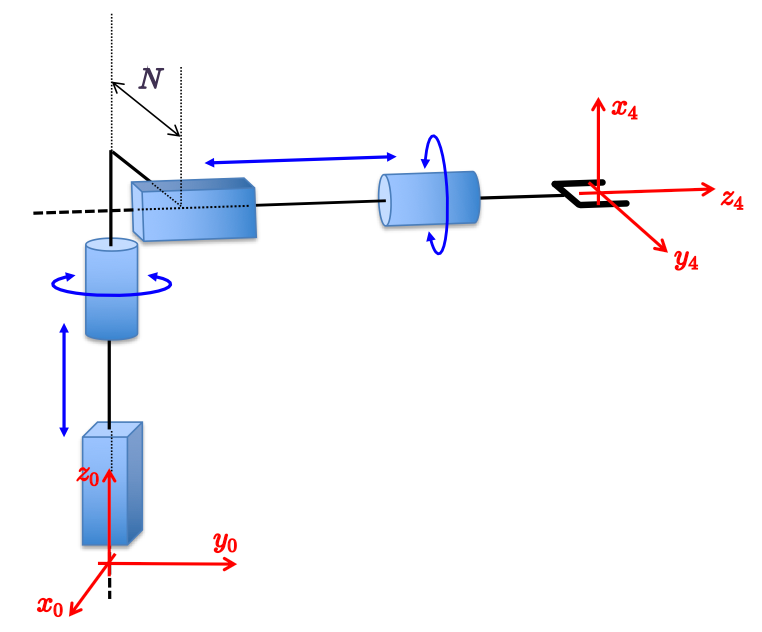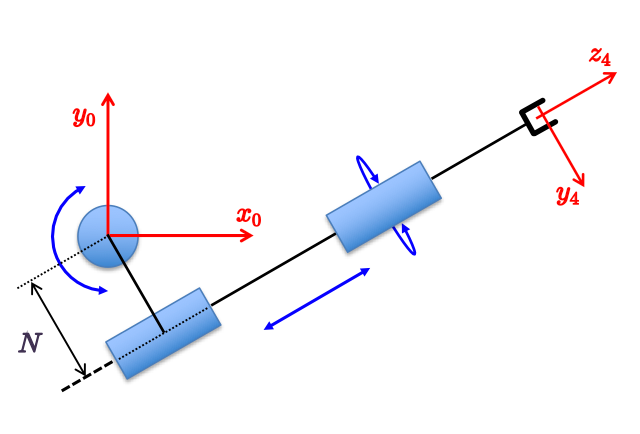

图1 PRPR机器人

解答：

（1）画出坐标系{1}，{2}。（每个5分，共10分）

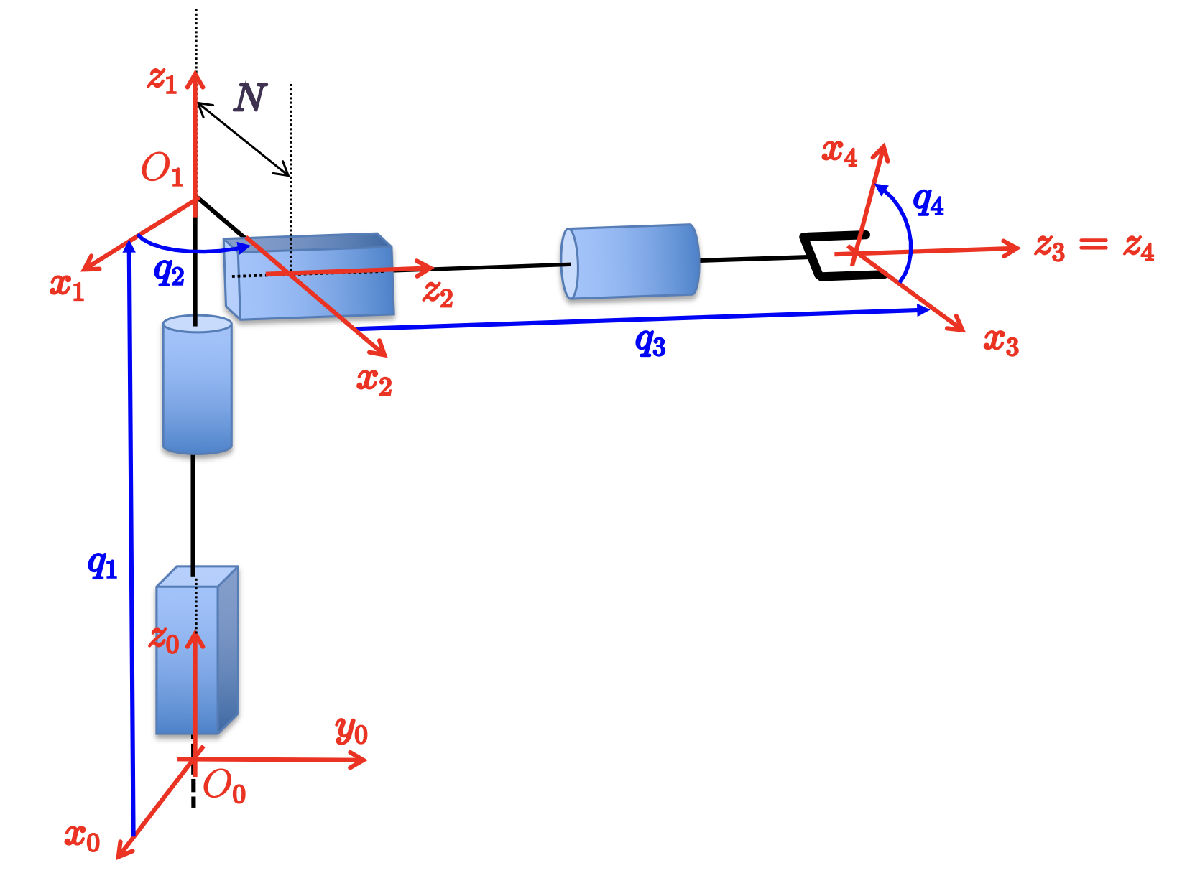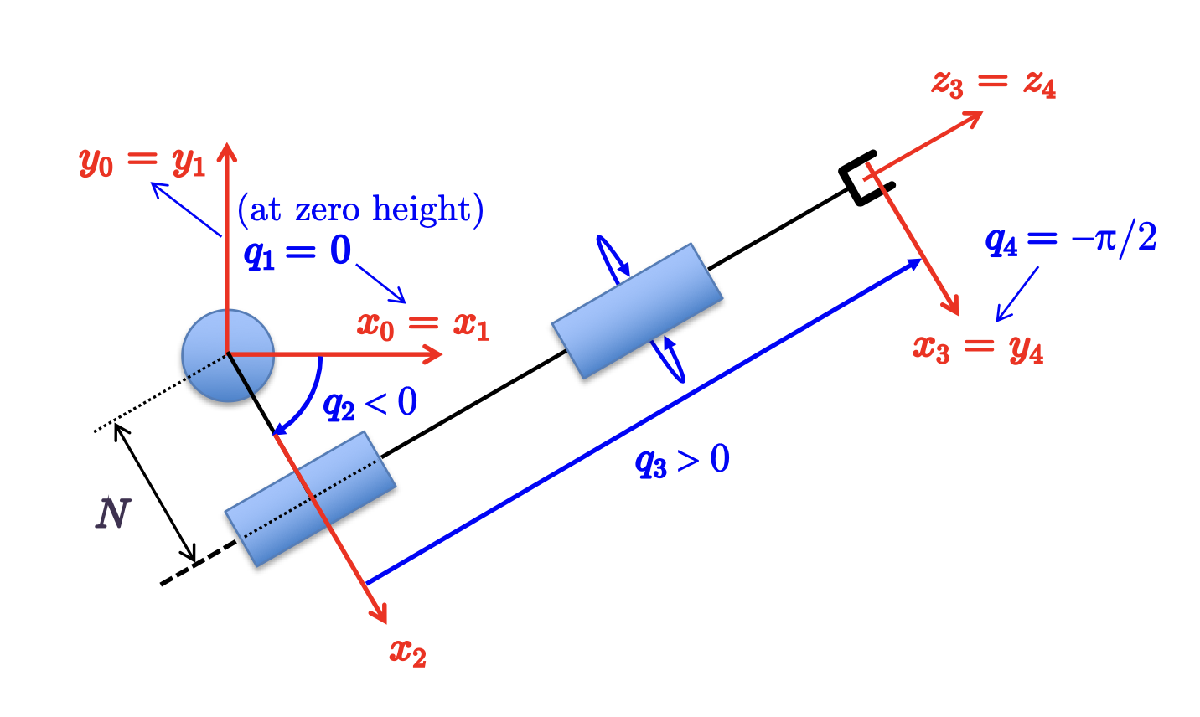

（2） 根据坐标系，列写DH参数表（5分）


$$\begin{array}{|c|c|c|c|c|}
\hline i & d_i & \theta_i & a_i  &\alpha_i \\
\hline 1 &  q_1 & 0    &0  & 0  \\
\hline 2 & 0 & q_2    &N &  -\pi / 2  \\
\hline 3 & q_3 & 0    & 0 & 0  \\
\hline 4 & 0 & q_4    & 0 & 0  \\
\hline
\end{array}$$


（3） 校验坐标系4的原点（10分）

syms q1 q2 q3 q4 N
 
T01 = transl([0; 0; q1])

$$T01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 =trotz(q2)*transl([N;0;0])*trotx(-pi/2)

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & N\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & N\,\sin\left(q_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T01*T12

$$ans = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & N\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & N\,\sin\left(q_{2}\right)\\ 0 & -1 & 0 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = transl([0; 0; q3])

$$T23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = T01*T12*T23

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & N\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & N\,\sin\left(q_{2}\right)+q_{3}\,\cos\left(q_{2}\right)\\ 0 & -1 & 0 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

第3题（30分）

如图2所示，平面$ $2 \mathrm{R}$$机器人 (标记为A ) 和平面$ $3 \mathrm{R}$$机器人 (标记为 B ) 的连杆均为单位长度，它们要在世界坐标系中通过末端执行器传递一个物体。在世界坐标系中, 两个机器人的基坐标系原点分别为:$ ${ }^w \mathbf{p}_A=\left[\begin{array}{ll}-2.5 & 1\end{array}\right]^{\top}$$和$ ^{w} \mathbf{p}_{B} = 
\left[ \begin{array}{ll}
1 & 2
\end{array}
\right]^{\top}$。机器人B的基座相对于$ \mathbf{x}_w$ 逆时针旋转了角度 $$\alpha_B=\pi / 6$$。机器人A在构型$$\mathbf{q}_A=\left[\begin{array}{ll}\pi / 3 & -\pi / 2\end{array}\right]^{\top}$$持有操作物体。请确定机器人B的构型，使其能够正确地抓住机器人A所持的物体（如图2右下角所示）。

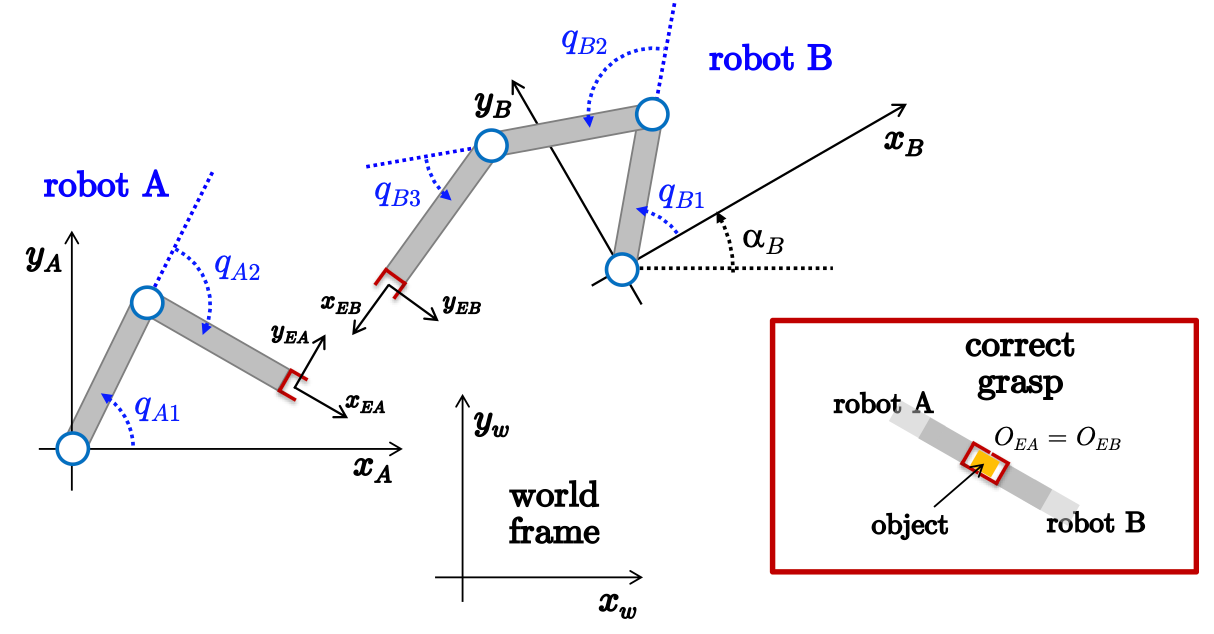

图2 机器人协同操作任务

解答：

(1) 机器人B的末端在坐标系{A}中的坐标变换矩阵；（10分）

   注意这里的绕Z轴转动$\pi$表示是机器人B的末端

clear
qA1 = pi/3; 
qA2 = -pi/2;

TeA = trotz(qA1)*transl([1;0;0])*trotz(qA2)*transl([1;0;0])*trotz(pi)

TeA =    -0.8660   -0.5000         0    1.3660
    0.5000   -0.8660         0    0.3660
         0         0    1.0000         0
         0         0         0    1.0000


(2) 机器人B的末端在坐标系{W}中的坐标变换矩阵;（3分）

TeW = transl([-2.5;1;0])*TeA

TeW =    -0.8660   -0.5000         0   -1.1340
    0.5000   -0.8660         0    1.3660
         0         0    1.0000         0
         0         0         0    1.0000


(3) 机器人B的末端在在坐标系B中的坐标变换矩阵;（7分）

alphaB = pi/6;
TeB = trotz(-alphaB)*transl([-1;-2;0])*TeW

TeB =    -0.5000   -0.8660         0   -2.1651
    0.8660   -0.5000         0    0.5179
         0         0    1.0000         0
         0         0         0    1.0000


(4-1) 在坐标系{B}中构建逆运动学问题(10分)

L(1) = Revolute('d', 0, 'a', 1, 'alpha', 0);
L(2) = Revolute('d', 0, 'a', 1, 'alpha', 0);
L(3) = Revolute('d', 0, 'a', 1, 'alpha', 0);
bot = SerialLink(L);
M = [1 1 0 0 0 1];


第一个猜测

q0 = [0,0,0];
qBa = ikine(bot,TeB,'mask',M,'q0',q0) /pi

qBa =    -0.7581   -0.3526   -0.2226


第二个猜测

q0 = -qBa*pi;
qBb = ikine(bot,TeB,'mask', M, 'q0', q0)/pi

qBb =     0.8893    0.3526   -0.5752


(4-2) 几何求解（10分）

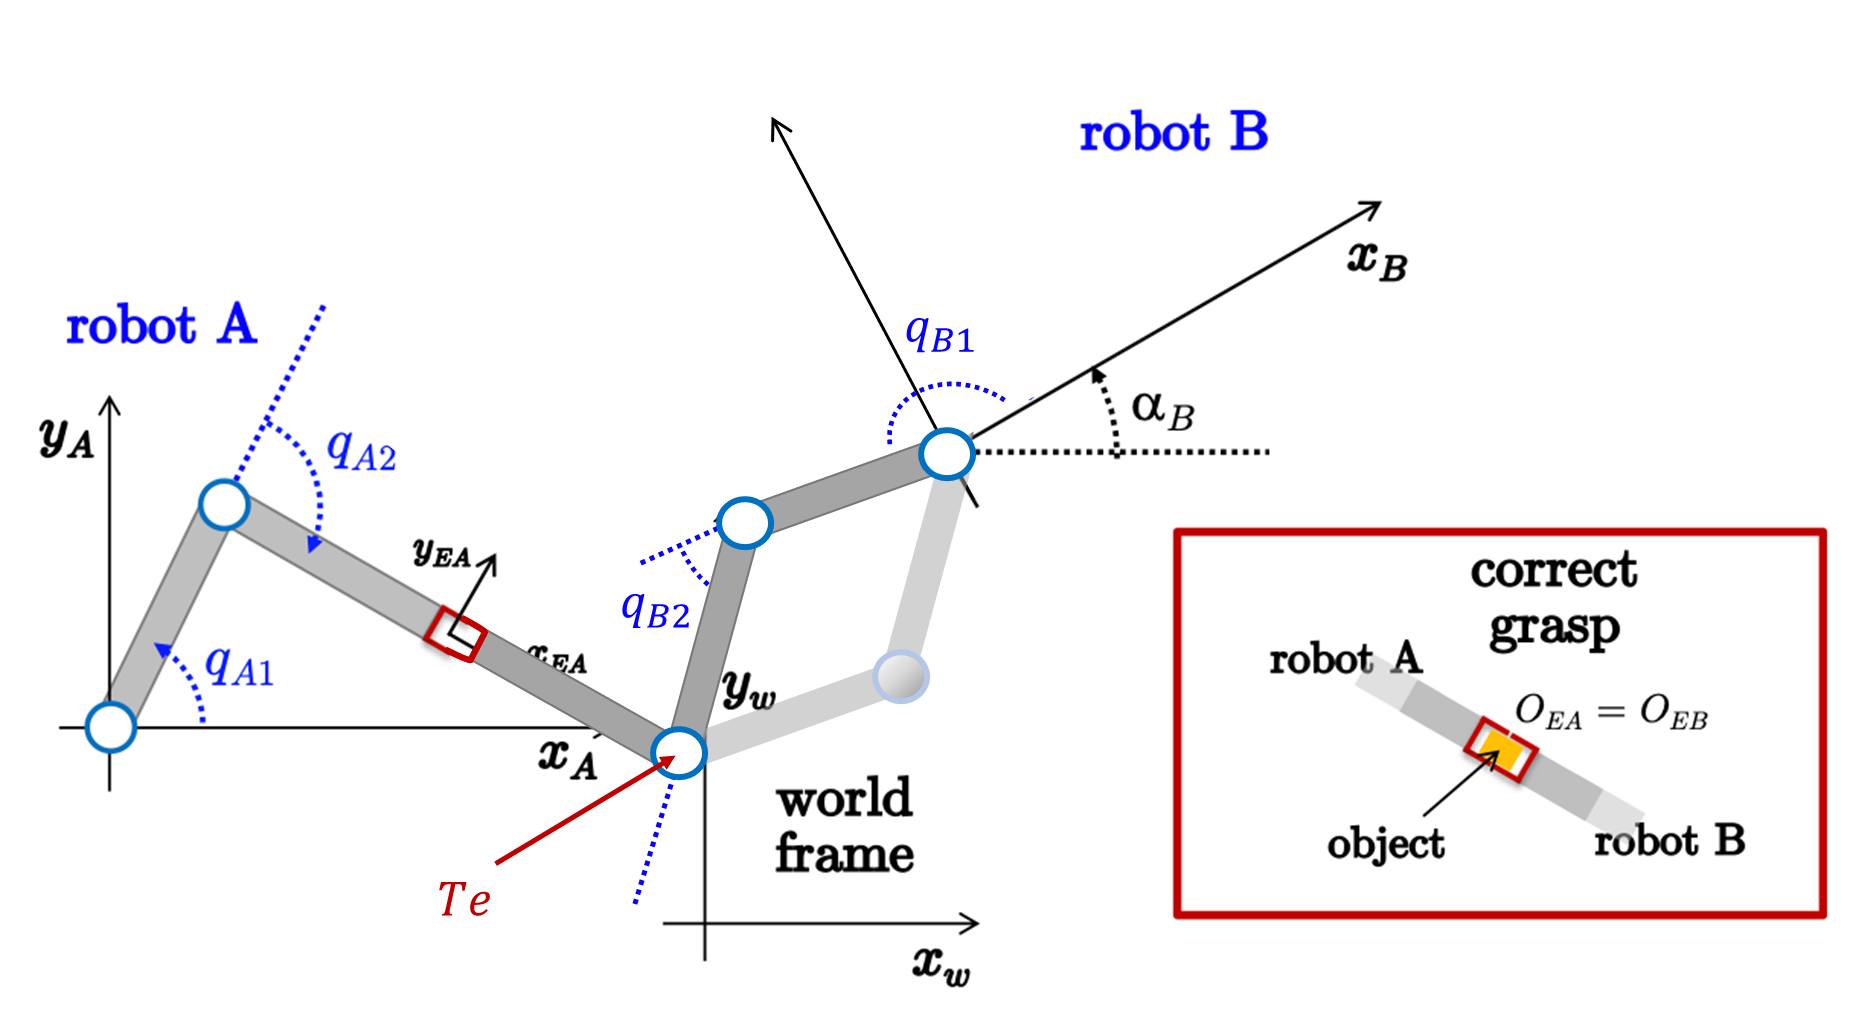

(4.2.1) 通过右下角的连接方式可以将机器人B的第三个连杆视为机器人A的第二个连杆的延长，两个机器人关节满足关系: 

alphaB + qB1 + qB2 + qB3  =  qA1 + qA2 + pi 。 此时机器人B末端Te在坐标系{A}中的齐次变换矩阵和相应x-y平面位置

TeA = trotz(sym(qA1))*transl([1;0;0])*trotz(sym(qA2))*transl([2;0;0]);
posA = TeA(1:2,4)'

$$posA = \left(\begin{array}{cc} \sqrt{3}+\frac{1}{2} & \frac{\sqrt{3}}{2}-1 \end{array}\right)$$

(4.2.2) 末端Te在坐标系{W}中的齐次变换矩阵和相应x-y平面位置

TeW = transl([-2.5;1;0])*TeA;
posW = TeW(1:2,4)'

$$posW = \left(\begin{array}{cc} \sqrt{3}-2 & \frac{\sqrt{3}}{2} \end{array}\right)$$

(4.2.3) 末端Te在坐标系{B}中的齐次变换矩阵和相应x-y平面位置

TeB = trotz(sym(-alphaB))*transl([-1;-2;0])*TeW;
posB = TeB(1:2,4)';
posB = [simplify(posB(1)), simplify(posB(2))];

(4.2.4) 在{B}系中的逆运动学问题即为求解以下方程组得到qB1,qB2

syms qb1 qb2

eqns = [cos(qb1)+cos(qb1+qb2) == posB(1);
        sin(qb1)+sin(qb1+qb2) == posB(2)]

$$eqns = \left(\begin{array}{c} \cos\left({\mathrm{qb}}_{1}+{\mathrm{qb}}_{2}\right)+\cos\left({\mathrm{qb}}_{1}\right)=\frac{1}{2}-\frac{5\,\sqrt{3}}{4}\\ \sin\left({\mathrm{qb}}_{1}+{\mathrm{qb}}_{2}\right)+\sin\left({\mathrm{qb}}_{1}\right)=\frac{9}{4}-\frac{3\,\sqrt{3}}{2} \end{array}\right)$$


% A.利用solve函数求解方程组
[q1, q2] = solve(eqns, [qb1, qb2]);
digits(32);
qBa = [vpa(q1(1)), vpa(q2(1))];

qBb = [vpa(q1(2)), vpa(q2(2))];
digits(5);
qBa = vpa(qBa/pi)

$$qBa = \left(\begin{array}{cc} 0.88931 & 0.35256 \end{array}\right)$$

qBb = vpa(qBb/pi)

$$qBb = \left(\begin{array}{cc} -0.75812 & -0.35256 \end{array}\right)$$


% B.手动计算
% 1.两式平方求和得到
2*cos(qb2) == simplify(posB(1)^2 + posB(2)^2 - 2)

$$ans = 2\,\cos\left({\mathrm{qb}}_{2}\right)=\frac{59}{4}-8\,\sqrt{3}$$


% acos得到qB2有两个解
qBa_2 = acos((59/4 - 8*sqrt(3))*0.5)

qBa_2 = 1.1076

qBb_2 = -acos((59/4 - 8*sqrt(3))*0.5)

qBb_2 = -1.1076


% 2.两式分别和差化积
eqns = [2*cos(qb1+qb2/2)*cos(qb2/2) == posB(1);
        2*sin(qb1+qb2/2)*cos(qb2/2) == posB(2)]

$$eqns = \left(\begin{array}{c} 2\,\cos\left({\mathrm{qb}}_{1}+\frac{{\mathrm{qb}}_{2}}{2}\right)\,\cos\left(\frac{{\mathrm{qb}}_{2}}{2}\right)=\frac{1}{2}-\frac{5\,\sqrt{3}}{4}\\ 2\,\sin\left({\mathrm{qb}}_{1}+\frac{{\mathrm{qb}}_{2}}{2}\right)\,\cos\left(\frac{{\mathrm{qb}}_{2}}{2}\right)=\frac{9}{4}-\frac{3\,\sqrt{3}}{2} \end{array}\right)$$


% 根据qB2的结果得到qB1+qB2/2
tmp = atan2((9/4 - 3*sqrt(3)/2)/(2*cos(0.5*qBa_2)), (0.5-5*sqrt(3)/4)/(2*cos(0.5*qBa_2)));
qBa_1 = tmp - qBa_2/2 + 2*pi % 回到(-pi,pi]区间

qBa_1 = 2.7939

tmp = atan2((9/4 - 3*sqrt(3)/2)/(2*cos(0.5*qBb_2)), (0.5-5*sqrt(3)/4)/(2*cos(0.5*qBb_2)));
qBb_1 = tmp - qBb_2/2

qBb_1 = -2.3817

(4.2.55) 得到qB1,qB2后，利用关系 alphaB + qB1 + qB2 + qB3 = qA1 + qA2 + pi 计算qB3

qBa = [qBa(1), qBa(2), vpa(pi/3 - pi/2 - alphaB -qBa(1) -qBa(2) + pi)]

$$qBa = \left(\begin{array}{ccc} 0.88931 & 0.35256 & 0.85252 \end{array}\right)$$

qBb = [qBb(1), qBb(2), vpa(pi/3 - pi/2 - alphaB -qBb(1) -qBb(2) + pi)]

$$qBb = \left(\begin{array}{ccc} -0.75812 & -0.35256 & 3.2051 \end{array}\right)$$

（5）补充验证程序

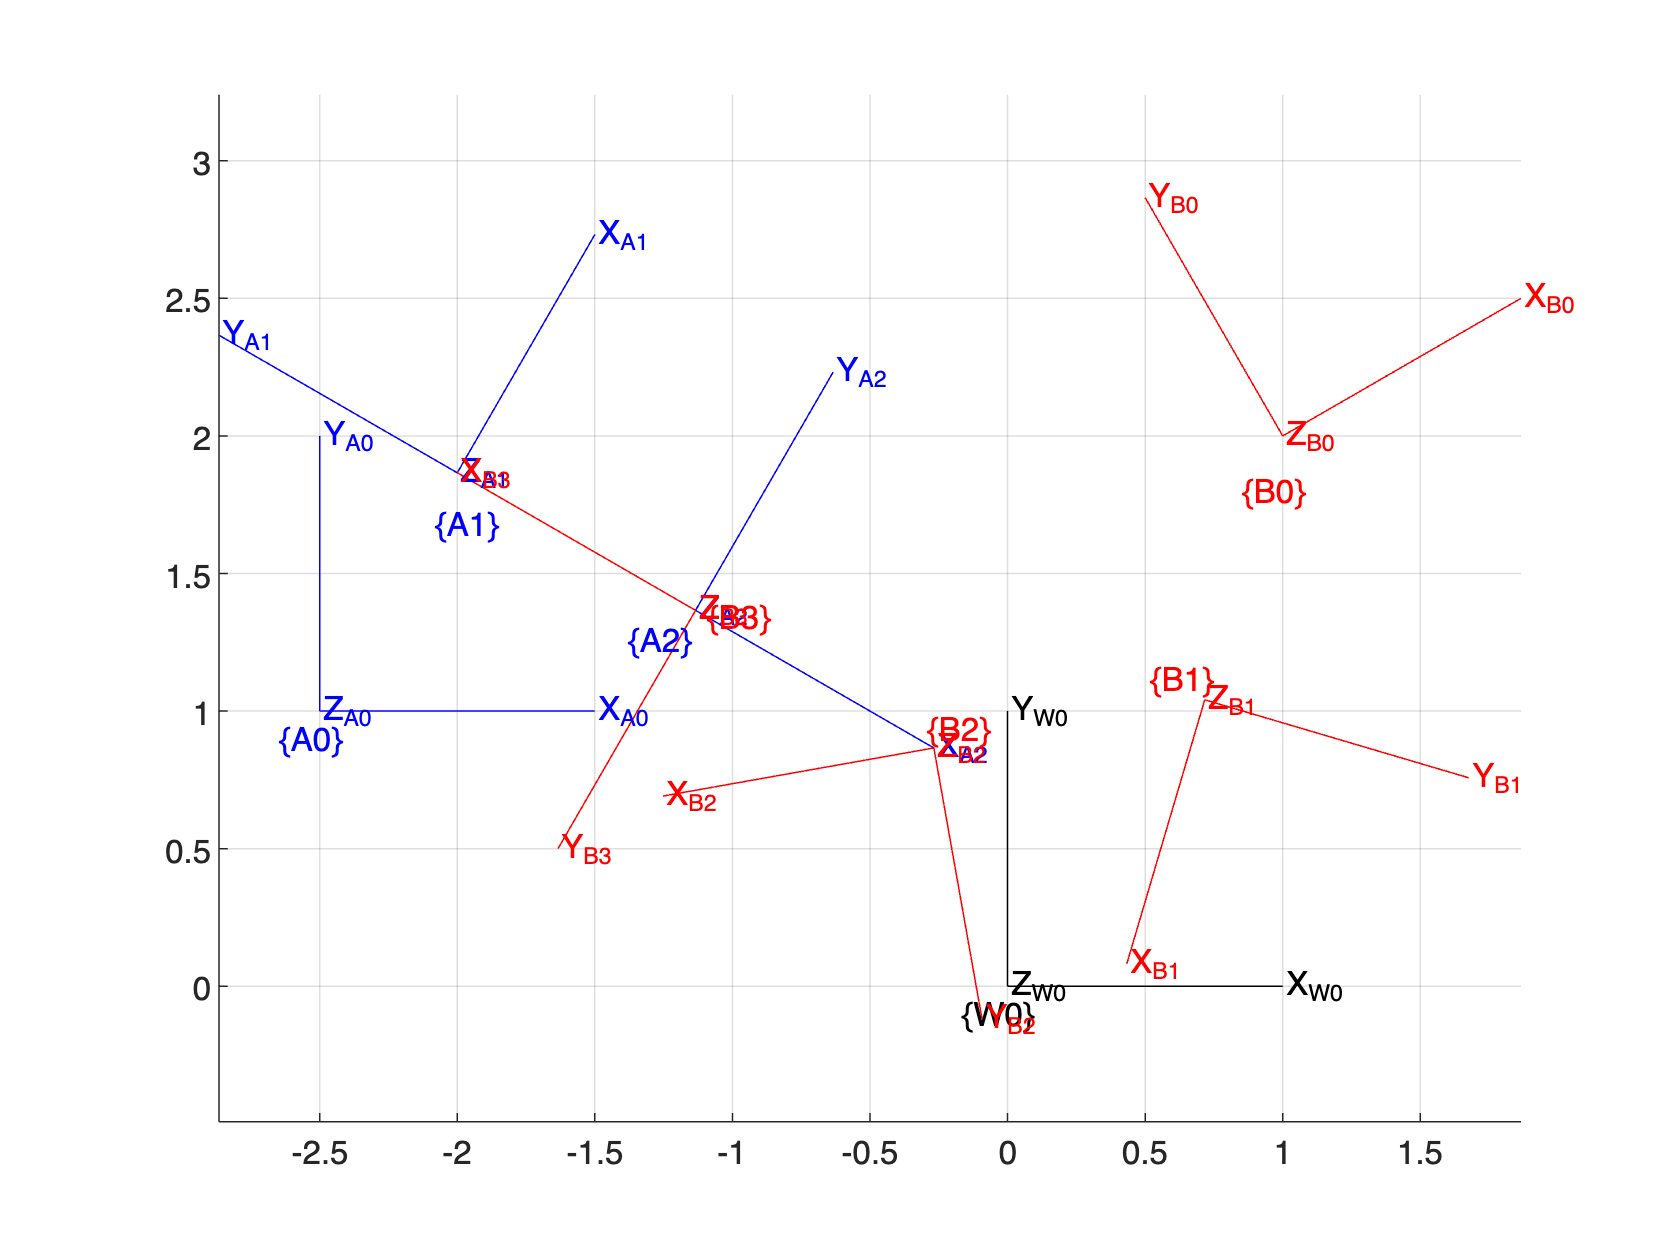

clear
close all
clc

figure; hold on;
axis equal
grid

% +++++++++++++++++++++++++++++++++++++++++++++++++++++
% 画出基坐标系
TW0 = transl([0;0;0]);
trplot(TW0, 'frame', 'W0', 'color', 'black');

qA1 = pi/3; 
qA2 = -pi/2;
TA0 = transl([-2.5;1;0]);
TA1 = TA0*trotz(qA1)*transl([1;0;0]);
TA2 = TA1*trotz(qA2)*transl([1;0;0]);

% 画出机器人A的坐标系
trplot(TA0, 'frame', 'A0', 'color', 'b');
trplot(TA1, 'frame', 'A1', 'color', 'b');
trplot(TA2, 'frame', 'A2', 'color', 'b');

% +++++++++++++++++++++++++++++++++++++++++++++++++++++
alphaB = pi/6;
qB1 = pi*(-0.7581); 
qB2 = pi*(-0.3526);
qB3 = pi/3 - pi/2 - alphaB -qB1 -qB2 + pi;

TB0 = transl([1;2;0])*trotz(alphaB);
TB1 = TB0*trotz(qB1)*transl([1;0;0]);
TB2 = TB1*trotz(qB2)*transl([1;0;0]);
TB3 = TB2*trotz(qB3)*transl([1;0;0]);

% 画出机器人B的各个坐标系
trplot(TB0, 'frame', 'B0', 'color', 'r');
trplot(TB1, 'frame', 'B1', 'color', 'r');
trplot(TB2, 'frame', 'B2', 'color', 'r');
trplot(TB3, 'frame', 'B3', 'color', 'r');


% +++++++++++++++++++++++++++++++++++++++++++++++++++++
TeB = trotz(qB1)*transl([1;0;0])*...
      trotz(qB2)*transl([1;0;0])*...
      trotz(qB3)*transl([1;0;0])

TeB =    -0.5000   -0.8660         0   -2.1650
    0.8660   -0.5000         0    0.5179
         0         0    1.0000         0
         0         0         0    1.0000


+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

第4题 （30分）

考虑图3中的PPR平面机器人，其中给出了坐标。第三连杆长度为。假设该机器人要执行的笛卡尔任务用其末端执行器的位置来定义，求其雅可比矩阵表示为，并找到关节速度的表达式，使最小化，同时实现期望的任务速度。

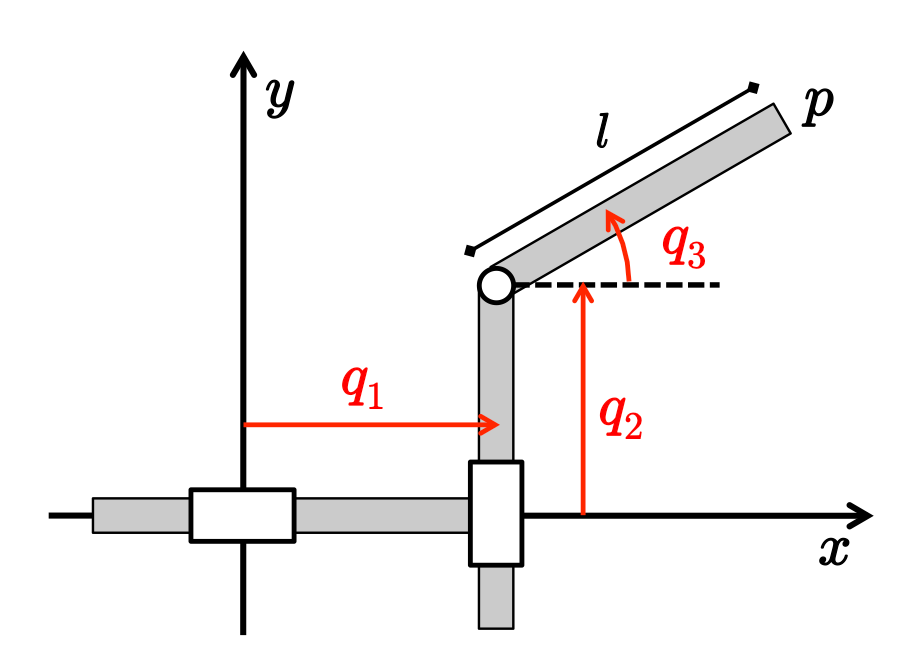

图3 PPR机器人示意图

解答：

(1) P的坐标（5分）

clear all
syms q1 q2 q3 l
q = [q1 q2 q3];


P=[q1+l*cos(q3);
    q2+l*sin(q3)];

(2) 雅可比矩阵（8分）

J = jacobian(P,q)

$$J = \left(\begin{array}{ccc} 1 & 0 & -l\,\sin\left(q_{3}\right)\\ 0 & 1 & l\,\cos\left(q_{3}\right) \end{array}\right)$$

(3) 伪逆矩阵（J#正确12分，数值正确5分）

J.'

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -l\,\sin\left(q_{3}\right) & l\,\cos\left(q_{3}\right) \end{array}\right)$$

J*J.'

$$ans = \left(\begin{array}{cc} l^{2}\,{\sin\left(q_{3}\right)}^{2}+1 & -l^{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)\\ -l^{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right) & l^{2}\,{\cos\left(q_{3}\right)}^{2}+1 \end{array}\right)$$

%inv(J*J.')
Jq = simplify(J.'/(J*J.'))

$$Jq = \begin{array}{l} \left(\begin{array}{cc} \frac{-l^{2}\,{\sin\left(q_{3}\right)}^{2}+l^{2}+1}{l^{2}+1} & \sigma_{1}\\ \sigma_{1} & \frac{l^{2}\,{\sin\left(q_{3}\right)}^{2}+1}{l^{2}+1}\\ -\frac{l\,\sin\left(q_{3}\right)}{l^{2}+1} & \frac{l\,\cos\left(q_{3}\right)}{l^{2}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l^{2}\,\sin\left(2\,q_{3}\right)}{2\,\left(l^{2}+1\right)} \end{array}$$

（4）第4题补充内容：

% digits规定运算精度
% subs是将符号替换成变量
digits(6)
Jq1 = subs(Jq,[l q3], vpa([0.5 pi/6]))

$$Jq1 = \left(\begin{array}{cc} 0.95 & 0.0866025\\ 0.0866025 & 0.85\\ -0.2 & 0.34641 \end{array}\right)$$

dP1 = [-1 1]';
dq1 = Jq1*dP1

$$dq1 = \left(\begin{array}{c} -0.863397\\ 0.763397\\ 0.54641 \end{array}\right)$$

% vpa是高精度运算
Jq2 = subs(Jq,[l q3], vpa([50 pi/6]))

$$Jq2 = \left(\begin{array}{cc} 0.7501 & 0.43284\\ 0.43284 & 0.2503\\ -0.009996 & 0.0173136 \end{array}\right)$$

dP2 = [-100 100]';
dq2 = Jq2*dP2

$$dq2 = \left(\begin{array}{c} -31.726\\ -18.254\\ 2.73096 \end{array}\right)$$

W = diag([1,1,l^2])

$$W = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & l^{2} \end{array}\right)$$

Jwq = simplify(inv(W)*J.'/(J*inv(W)*J.'))

$$Jwq = \left(\begin{array}{cc} 1-\frac{{\sin\left(q_{3}\right)}^{2}}{2} & \frac{\sin\left(2\,q_{3}\right)}{4}\\ \frac{\sin\left(2\,q_{3}\right)}{4} & \frac{{\sin\left(q_{3}\right)}^{2}}{2}+\frac{1}{2}\\ -\frac{\sin\left(q_{3}\right)}{2\,l} & \frac{\cos\left(q_{3}\right)}{2\,l} \end{array}\right)$$

Jwq1 = subs(Jwq,[l q3], vpa([0.5 pi/6]));
dwq1 = Jwq1*dP1

$$dwq1 = \left(\begin{array}{c} -0.658494\\ 0.408494\\ 1.36603 \end{array}\right)$$

Jwq2 = subs(Jwq,[l q3], vpa([50 pi/6]));
dwq2 = Jwq2*dP2

$$dwq2 = \left(\begin{array}{c} -65.8494\\ 40.8494\\ 1.36603 \end{array}\right)$$

这是因为：


$${\bf{J}}^{\#}(\bf{q})
=\bf{J}^T(\bf{q})\left(\bf{J}(\bf{q}) \bf{J}^T(\bf{q})\right)^{-1}
=\frac{1}{1+l^2}\left(\begin{array}{cc}
1+l^2 \cos ^2 q_3 & l^2 \sin q_3 \cos q_3 \\
l^2 \sin q_3 \cos q_3 & 1+l^2 \sin ^2 q_3 \\
-l \sin q_3 & l \cos q_3
\end{array}\right)$$


当查看${\bf{J}}^{\#}$中矩阵的元素时，容易意识到其中的元素存在单位不一致的问题。$det(\bf{J})=\bf{J}\bf{J}^T=1+l^2$，行列式的表达式是：一个无量纲的量和一个量纲为长度平方的量的和。

如：

(1)$l=0.5[\mathrm{~m}], \quad q_3=\pi / 6[\mathrm{rad}], \quad \dot{\bf{p}}=\left(\begin{array}{r}
-1 \\
1
\end{array}\right)[\mathrm{m} / \mathrm{s}]$，则$\dot{\bf{q}}=\left(\begin{array}{cc}
0.95 & 0.0866 \\
0.0866 & 0.85 \\
-0.2 & 0.3464
\end{array}\right)\left(\begin{array}{r}
-1 \\
1
\end{array}\right)=\left(\begin{array}{c}
-0.8634\quad{[\mathrm{m} / \mathrm{s}]}  \\
0.7634\quad {[\mathrm{m} / \mathrm{s}]} \\
0.5464\quad{[\mathrm{rad} / \mathrm{s}]}
\end{array}\right) $

(2)$l=50[\mathrm{~cm}], \quad q_3=\pi / 6[\mathrm{rad}], \quad \dot{\bf{p}}=\left(\begin{array}{r}
-100 \\
100
\end{array}\right)[\mathrm{cm} / \mathrm{s}]$，则$\dot{\bf{q}}=\left(\begin{array}{cc}
0.7501 & 0.4328 \\
0.4328 & 0.2503 \\
-0.01 & 0.0173
\end{array}\right)\left(\begin{array}{r}
-100 \\
100
\end{array}\right)=\left(\begin{array}{c}
-31.72 \quad{[\mathrm{cm} / \mathrm{s}]}  \\
-18.25 \quad{[\mathrm{cm} / \mathrm{s}]} \\
2.731 \quad{[\mathrm{rad} / \mathrm{s}]}
\end{array}\right) 

$

可以看出其中的$\dot{\bf{p}}$和$\dot{\bf{q}}$的量纲的不协调。

回归到原始定义：$\dot{\bf{q}}={\bf{J}}_W^{\#}(\bf{q}) \dot{\bf{p}}$

${\bf{J}}_{\bf{W}}^{\#}(\bf{q})={\bf{W}}^{-1} \bf{J}^T(\bf{q})\left(\bf{J}(\bf{q}) \bf{W}^{-1} \bf{J}^T(\bf{q})\right)^{-1}$，其中${\bf{W}}=\left(\begin{array}{lll}
1 & & \\
& 1 & \\
& & w
\end{array}\right)$

则，$\left(\bf{J}(\bf{q}) \bf{W}^{-1} \bf{J}^T(\bf{q})\right)^{-1}=\left(\begin{array}{ll}
1+\frac{l^2}{w} \sin ^2 q_3 & \frac{l^2}{w} \sin q_3 \cos q_3 \\
\frac{l^2}{w} \sin q_3 \cos q_3 & 1+\frac{l^2}{w} \cos ^2 q_3
\end{array}\right)$，即${det}\left(\bf{J} \bf{W}^{-1} \bf{J}^T\right)=1+\frac{l^2}{w}$

${\bf{J}}_{\bf{W}}^{\#}(\bf{q})=\frac{1}{2}\left(\begin{array}{cc}
1+\cos ^2 q_3 & \sin q_3 \cos q_3 \\
\sin q_3 \cos q_3 & 1+\sin ^2 q_3 \\
-\frac{\sin q_3}{l} & \frac{\cos q_3}{l}
\end{array}\right)$($w=l^2$)

(1)$l=0.5[\mathrm{~m}], \quad q_3=\pi / 6[\mathrm{rad}], \quad \dot{\bf{p}}=\left(\begin{array}{r}
-1 \\
1
\end{array}\right)[\mathrm{m} / \mathrm{s}]$，则$\dot{\bf{q}}=\left(\begin{array}{cc}
0.875 & 0.2165 \\
0.2165 & 0.625 \\
-0.5 & 0.866
\end{array}\right)\left(\begin{array}{r}
-1 \\
1
\end{array}\right)=\left(\begin{array}{c}
-0.6585\quad  {[\mathrm{m} / \mathrm{s}]}\\
0.4085 \quad {[\mathrm{m} / \mathrm{s}]}\\
1.366 \quad {[\mathrm{rad} / \mathrm{s}]}
\end{array}\right) $

(2)$l=50[\mathrm{~cm}], \quad q_3=\pi / 6[\mathrm{rad}], \quad \dot{\bf{p}}=\left(\begin{array}{r}
-100 \\
100
\end{array}\right)[\mathrm{cm} / \mathrm{s}]$，则$\dot{\bf{q}}=\left(\begin{array}{cc}
0.875 & 0.2165 \\
0.2165 & 0.625 \\
-0.005 & 0.0087
\end{array}\right)\left(\begin{array}{c}
-100 \\
100
\end{array}\right)=\left(\begin{array}{c}
-65.8484 \quad{[\mathrm{cm} / \mathrm{s}]}\\
-40.8494 \quad{[\mathrm{cm} / \mathrm{s}]}\\
1.366 \quad{[\mathrm{rad} / \mathrm{s}]}
\end{array}\right) 
=\left(\begin{array}{c}
-0.6585 \quad {[\mathrm{m} / \mathrm{s}]}\\
0.4085 \quad {[\mathrm{m} / \mathrm{s}]}\\
1.366 \quad {[\mathrm{rad} / \mathrm{s}]}
\end{array}\right) $

可以看出这样处理后$\dot{\bf{p}}$和$\dot{\bf{q}}$的量纲的协调的。